# Trajectory Planning

clear;
close all;
clc;

## Task A: RR Robot arm

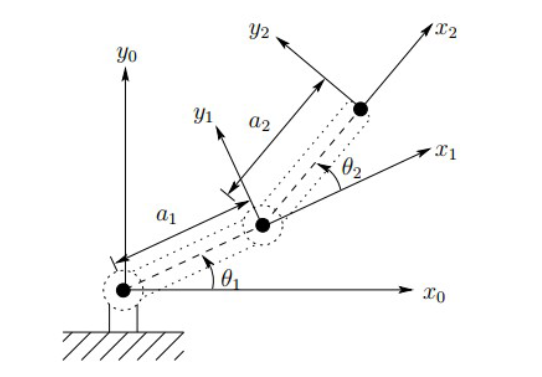

### Initial variables and parameters:

- $a_1$: 1m

- $a_2$: 0.75 m

- $\theta_1$: 10°

- $\theta_2$: 45°

- $x$: 1.4150 m

- $y$: 0.7880 m

a1 = 1;
a2 = 0.75;
theta1_init = deg2rad(10);
theta2_init = deg2rad(45);
X2_init = 1.415;
Y2_init = 0.788;

### Obejctive:

- We want the operator to move in a smooth manner, so that in **3.5 seconds** the tip is in the position **(x, y) = (1.4406, 0.9821)** where it will be immobilized.

- Determine the trajectories of the variables of its joints and give the graphs of their **position**, **velocity** and **acceleration** as a function of time.

X2_end = 1.4406;
Y2_end = 0.9821;

X2_traj = [X2_init, X2_end];
Y2_traj = [Y2_init, Y2_end];

t_end = 3.5;

### Forward kinematics equations:

The known forward kinematics equations are:


$$\begin{array}{l}
x=a_1 \cdot \cos \left(\theta_1 \right)+a_2 \cdot \cos \left(\theta_1 +\theta_2 \right)\\
y=a_1 \cdot \sin \left(\theta_1 \right)+a_2 \cdot \sin \left(\theta_1 +\theta_2 \right)
\end{array}$$


### Visualization of the work space:

For optimal tracetory planning first the visualization of the work space and the planned position path should be performed.

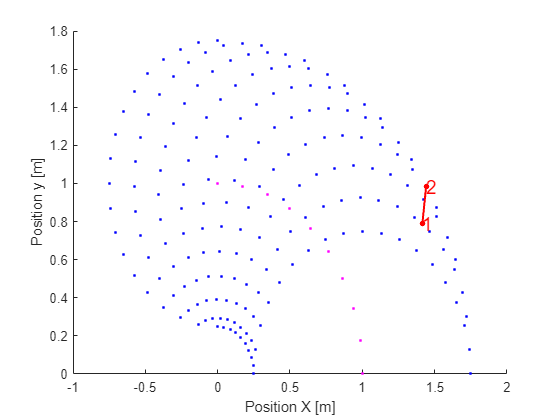

% All possible angle for theta1 and theta2 in the selected frame are 0 to
% 90°
theta1 = 0:10:90;
theta2 = 0:10:180;

% Convert deg in rad
theta1 = deg2rad(theta1);
theta2 = deg2rad(theta2);

% Generate grid of angle values
[THETA1,THETA2] = meshgrid(theta1,theta2);

% Calculate all possible X and Y positions
X1 = a1.*cos(THETA1);
Y1 = a1.*sin(THETA1);
X2 = X1 + a2.*cos(THETA1 + THETA2);
Y2 = Y1 + a2.*sin(THETA1 + THETA2);

% Visualization
figure
hold on
plot(X1,Y1,'m.')
plot(X2,Y2,'b.')
plot(X2_traj,Y2_traj,'r.','LineStyle','-','MarkerSize',12,'LineWidth',1.5)
text(X2_traj(1),Y2_traj(1),'1','Color','r','FontSize',14)
text(X2_traj(2),Y2_traj(2),'2','Color','r','FontSize',14)
hold off

xlabel('Position X [m]')
ylabel('Position y [m]')

### Inverse kinematics equations:

With the geometric method the inverse kinematics equations can be formulated to calculate the joint angles:


$$\theta_2 =\arccos \left(\frac{x^2 +y^2 -a_1^2 -a_2^2 }{2a_1 a_2 }\right)$$



$$\theta_1 =\arctan \left(\frac{y}{x}\right)-\arctan \left(\frac{a_2 \sin \left(\theta_2 \right)}{a_1 +a_2 \cos \left(\theta_2 \right)}\right)$$


### Position trajectory

To get a smooth position trajectory an asymptotic step response was selected.

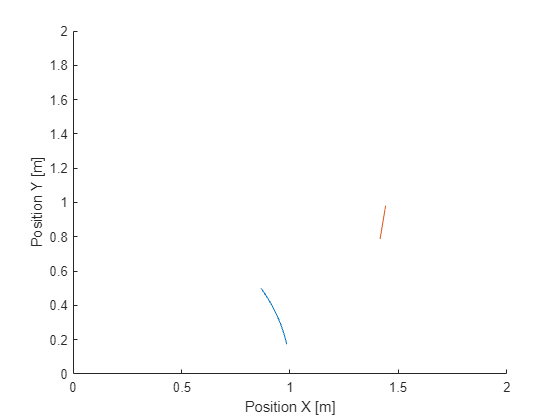

% Calculate stationary values
X2_stat = abs(X2_init - X2_end);
Y2_stat = abs(Y2_init - Y2_end);

% Define state space model for smooth position trajectory
sys = ss(-t_end,t_end,1,0);

% Time array
t = 0:0.01:5;

% Input for X and Y position 
uX = ones(length(t),1).*X2_end;
uY = ones(length(t),1).*Y2_end;

% Simulate X position trajectory 
X2ref = lsim(sys,uX,t,X2_init);
Y2ref = lsim(sys,uY,t,Y2_init);

% Calculate joint angles
theta2 = acos((X2ref.^2 + Y2ref.^2 - a1^2 - a2^2)/(2*a1*a2));
theta1 = atan(Y2ref./X2ref) - atan((a2.*sin(theta2))./(a1 + a2.*cos(theta2)));

% Calculate position values
X1 = a1.*cos(theta1);
Y1 = a1.*sin(theta1);
X2 = X1 + a2.*cos(theta1 + theta2);
Y2 = Y1 + a2.*sin(theta1 + theta2);

% Calculate velocities & accelerations
X1_dot = diff(X1);
X2_dot = diff(X2);
Y1_dot = diff(Y1);
Y2_dot = diff(Y2);
X1_ddot = diff(diff(X1));
X2_ddot = diff(diff(X2));
Y1_ddot = diff(diff(Y1));
Y2_ddot = diff(diff(Y2));

theta1_dot = diff(theta1);
theta2_dot = diff(theta2);
theta1_ddot = diff(diff(theta1));
theta2_ddot = diff(diff(theta2));

% Plot trajectory
figure
hold on
plot(X1,Y1)
plot(X2,Y2)
hold off

xlim([0 2])
ylim([0 2])
xlabel('Position X [m]')
ylabel('Position Y [m]')

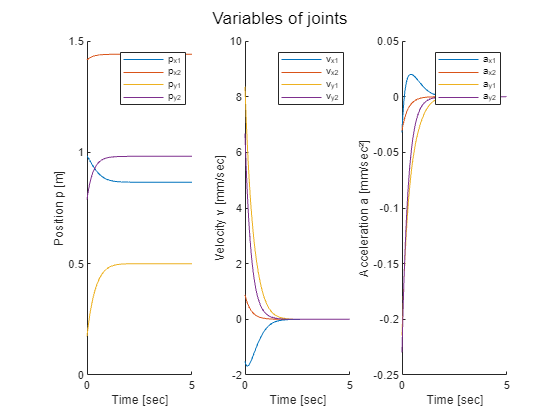

% Plot joint position, velocity and acceleration
figure
subplot(1,3,1)
hold on
plot(t,X1,'DisplayName','p_x_1')
plot(t,X2,'DisplayName','p_x_2')
plot(t,Y1,'DisplayName','p_y_1')
plot(t,Y2,'DisplayName','p_y_2')
hold off
legend
xlabel('Time [sec]')
ylabel('Position p [m]')

subplot(1,3,2)
hold on
plot(t(1:end-1),X1_dot.*1e3,'DisplayName','v_x_1')
plot(t(1:end-1),X2_dot.*1e3,'DisplayName','v_x_2')
plot(t(1:end-1),Y1_dot.*1e3,'DisplayName','v_y_1')
plot(t(1:end-1),Y2_dot.*1e3,'DisplayName','v_y_2')
hold off
legend
xlabel('Time [sec]')
ylabel('Velocity v [mm/sec]')

subplot(1,3,3)
hold on
plot(t(1:end-2),X1_ddot.*1e3,'DisplayName','a_x_1')
plot(t(1:end-2),X2_ddot.*1e3,'DisplayName','a_x_2')
plot(t(1:end-2),Y1_ddot.*1e3,'DisplayName','a_y_1')
plot(t(1:end-2),Y2_ddot.*1e3,'DisplayName','a_y_2')
hold off
legend
xlabel('Time [sec]')
ylabel('Acceleration a [mm/sec²]')
sgtitle('Variables of joints')

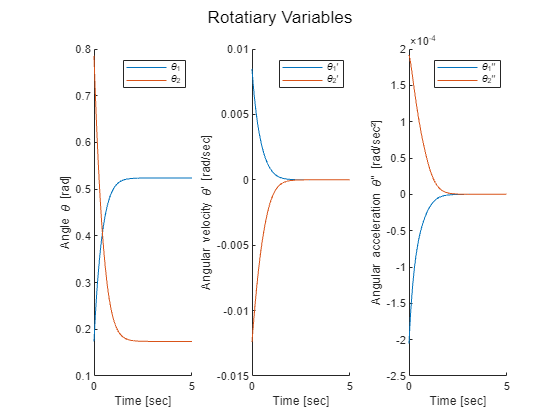

% Plot angle, angular velocity and acceleration
figure
subplot(1,3,1)
hold on
plot(t,theta1,'DisplayName','\theta_1')
plot(t,theta2,'DisplayName','\theta_2')
hold off
legend
xlabel('Time [sec]')
ylabel('Angle \theta [rad]')

subplot(1,3,2)
hold on
plot(t(1:end-1),theta1_dot,'DisplayName','\theta_1\prime')
plot(t(1:end-1),theta2_dot,'DisplayName','\theta_2\prime')
hold off
legend
xlabel('Time [sec]')
ylabel('Angular velocity \theta\prime [rad/sec]')

subplot(1,3,3)
hold on
plot(t(1:end-2),theta1_ddot,'DisplayName','\theta_1\prime\prime')
plot(t(1:end-2),theta2_ddot,'DisplayName','\theta_2\prime\prime')
hold off
legend
xlabel('Time [sec]')
ylabel('Angular acceleration \theta\prime\prime [rad/sec²]')
sgtitle('Rotatiary Variables')

## Task B: Cubic Trajectory

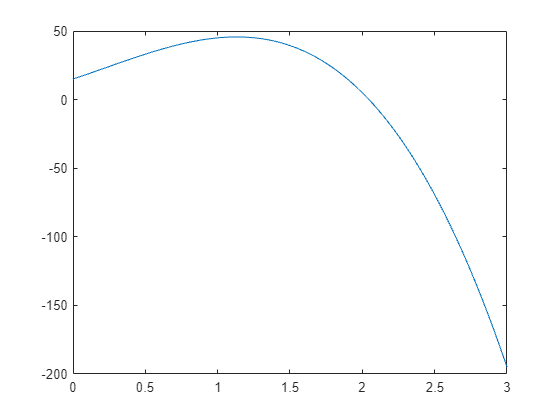

clear;
clc;

% Cubic trajectory function
theta = @(t) 15 + 35.*t + 10.*t.^2 - 15.*t.^3;

% Time array from 0 to 3 sec's
t = 0:0.01:3;

figure
plot(t,theta(t))